Load Data

clear; clc;


% readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Price Data")
priceDS = datastore ("Trend Trading Input Output Data.xlsx","Sheets","Price Data")

priceDS =   SpreadsheetDatastore with properties:

                      Files: {
                             ' ...\Project-Repo-Test\Trend Trading Input Output Data.xlsx'
                             }
                    Folders: {
                             ' ...\kiki.mulyadi\Desktop\Matlab Investment R&D and Live\Project-Repo-Test'
                             }
   AlternateFileSystemRoots: {}
                     Sheets: 'Price Data'
                      Range: ''

  Sheet Format Properties:
             NumHeaderLines: 0
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'Time', 'AALI', 'ABBA' ... and 663 more}
              VariableTypes: {'datetime', 'double', 'double' ... and 663 more}

  Properties that control the table returned by preview, <a href

% pricedata.SelectedVariableNames;

% convert ds to tall table
priceTall = tall (priceDS);

% conevrt tall table to tall timetable

priceTall = table2timetable (priceTall);
head (priceTall)

ans =

  8×665 tall timetable

       Time            AALI        ABBA       ABDA       ABMM    ACES    ACST    ADES       ADHI       ADMF    ADMG    ADRO    AGAR    AGII       AGRO       AGRS      AHAP       AIMS      AISA         AKKU       AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN


clear priceDS



Data cleaning

tic

priceTT = fillmissing (priceTall, 'previous');
priceTT = fillmissing (priceTT, 'next');
priceTT = gather (priceTT);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 3: Completed in 19 sec
- Pass 2 of 3: Completed in 24 sec
- Pass 3 of 3: Completed in 24 sec
Evaluation completed in 1 min 16 sec


priceTT = tall (priceTT);
head (priceTT)

ans =

  8×665 tall timetable

       Time            AALI        ABBA       ABDA       ABMM    ACES       ACST        ADES       ADHI       ADMF    ADMG    ADRO    AGAR    AGII       AGRO       AGRS      AHAP       AIMS      AISA         AKKU       AKPI    AKRA    AKSI       ALDO       ALKA    ALMI       ALTO       AMAG    AMAN    AMAR    AMFG



toc

Elapsed time is 101.048514 seconds.


Cumulative return

cumret = ret2tick (tick2ret (priceTT));
cumret = gather (cumret);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 3: Completed in 5 sec
- Pass 2 of 3: Completed in 3.7 sec
- Pass 3 of 3: Completed in 2.4 sec
Evaluation completed in 12 sec


cumretvar = cumret.Variables; 
cumretend = cumretvar (end,:);

cumretThreshold = 10;
buyidx = cumretend > cumretThreshold

buyidx = 1×665 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   0   0


cumretendHighValue = cumretend(buyidx)

cumretendHighValue = 	1.0e+02 *

   0.325385708180001   0.177884615384614   0.193288590604026   0.589595375722542   0.106617454793869   0.101259932789327   0.115384615384615   0.147727272727272   0.111675126903553   0.224761904761905   0.257154176008413   0.207226566057769   0.129032261966701   0.309589041095890   0.178823529411765   0.179999999999999   1.137755102040812   0.269879518072287   0.131955786914285   0.110734129753701   0.116666666666667   0.119607843137254   0.199212598425197   0.540540540540541   0.114516129032257   0.109797293587929   0.183666023928343   0.221216937006623   0.170930725805912   0.372702722848795   0.167407407407407   0.200000000000000   0.120161290322579   0.164666666666667   0.474358974358975   0.280000000000000   0.341880341880343   0.110185185185185   0.263235294117647   0.382165605095541   0.172613055897828   0.104482758620690   0.188000000000000


cumretendHighSymb = cumret.Properties.VariableNames (buyidx)

cumretendHighSymb = 1×43 cell array
    {'ABDA'}    {'AMRT'}    {'ARNA'}    {'ARTO'}    {'BRNA'}    {'CENT'}    {'CLEO'}    {'CPIN'}    {'CSMI'}    {'DCII'}    {'DEFI'}    {'DNET'}    {'EKAD'}    {'EMTK'}    {'ERTX'}    {'GEMA'}    {'GMTD'}    {'INAF'}    {'INDS'}    {'ITMA'}    {'JECC'}    {'JTPE'}    {'KAEF'}    {'KONI'}    {'MAPI'}    {'MARK'}    {'MREI'}    {'MTDL'}    {'MYOR'}    {'PSAB'}    {'PTDU'}    {'PTSP'}    {'SCMA'}    {'SKLT'}    {'SLIS'}    {'STTP'}    {'TCPI'}    {'TECH'}    {'TGKA'}    {'TOWR'}    {'TPIA'}    {'ULTJ'}    {'ZBRA'}



clear cumretvar cumret 


Selected variables

SelectedVarNames = cumretendHighSymb;
SelectedVarNames = sort (SelectedVarNames);
priceSample = priceTT (:, SelectedVarNames);
head (priceSample)

ans =

  8×43 tall timetable

       Time           ABDA       AMRT    ARNA     ARTO       BRNA         CENT       CLEO    CPIN    CSMI    DCII      DEFI          DNET          EKAD       EMTK     ERTX     GEMA    GMTD    INAF       INDS         ITMA       JECC    JTPE    KAEF    KONI    MAPI      MARK          MREI         MTDL          MYOR         PS

Build signal

% SMA 30
tic

WindowSize = 30;
priceSample = gather (priceSample);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 0.67 sec
Evaluation completed in 0.69 sec


priceSMA = movavg (priceSample,'simple', WindowSize);
head (priceSMA)

ans = 8×43 timetable
       Time              ABDA                AMRT                ARNA          ARTO          BRNA                CENT          CLEO          CPIN          CSMI    DCII      DEFI          DNET             EKAD           EMTK      ERTX     GEMA    GMTD          INAF              INDS          ITMA             JECC          JTPE          KAEF                KONI                MAPI            MARK             MREI                MTDL                MYOR            



SMA_Signal= priceSample.Variables > priceSMA.Variables;
A = SMA_Signal;

SMA_Signal(2:end,:) = A(1:end-1,:);
SMA_Signal(1,:) = 0;

SMA_SignalTT = priceSample;
SMA_SignalTT.Variables = SMA_Signal;

toc

Elapsed time is 1.361365 seconds.


Transaction cost adjustment

tic

buyFee = 0.2/100;
sellFee = 0.3/100;

SMASignTemp = SMA_SignalTT.Variables;
SMA_SignalShiftOneBackward = SMA_SignalTT;
SMASignShiftTemp = SMA_SignalShiftOneBackward.Variables;

SMASignShiftTemp (1,:) = 0;
SMASignShiftTemp(2:end,:) = SMASignTemp (1:end-1,:);

SMA_SignalTT.Variables = SMASignTemp;
SMA_SignalShiftOneBackward.Variables = SMASignShiftTemp;

buyidx = SMA_SignalShiftOneBackward.Variables == 0 & SMA_SignalTT.Variables == 1 ;
buycost = SMA_SignalTT;
buycost.Variables = buyidx .*(1) .* buyFee;

tail (SMA_SignalTT);
tail (SMA_SignalShiftOneBackward);
tail (buycost);

sellidx = SMA_SignalShiftOneBackward.Variables == 1 & SMA_SignalTT.Variables == 0 ;
sellcost = SMA_SignalTT;
sellcost.Variables = sellidx .* (-1) .* sellFee;

tail (SMA_SignalTT);
tail (SMA_SignalShiftOneBackward);
tail (sellcost);

transactionCost = SMA_SignalTT;
transactionCost.Variables = buycost.Variables + sellcost.Variables;

tail (buycost);
tail (sellcost);
tail (transactionCost);

clear SMASignShiftTemp SMASignTemp SMA_SignalShiftOneBackward
clear priceSMA buyidx buycost sellidx sellcost

% SMA_Signal = tall (SMA_Signal); 

toc

Elapsed time is 0.204065 seconds.


Cumret for trading on each symbol 

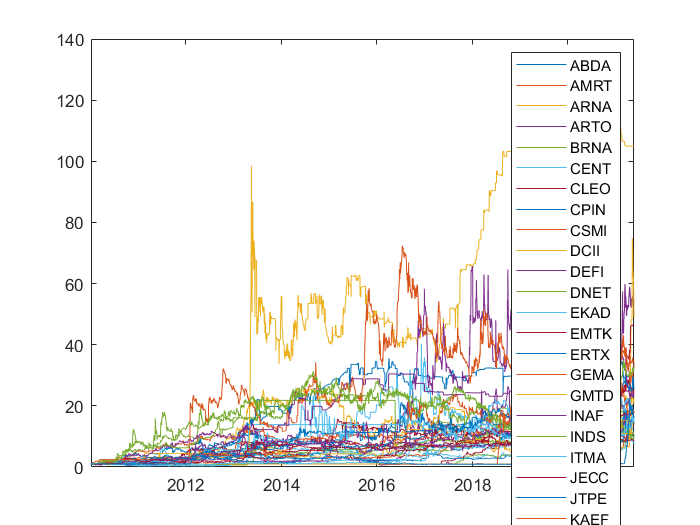

tic

retSym = tick2ret (priceSample);
netretsym = retSym;
transactionCostVariables = transactionCost.Variables;
netretsym.Variables = retSym.Variables + transactionCostVariables(2:end,:);

tail (SMA_SignalTT);
tail (retSym);
tail (netretsym);

cumretSym = ret2tick (netretsym);

plot (cumretSym.Time, cumretSym.Variables)
legend (cumretSym.Properties.VariableNames)


cumretSym = tall (cumretSym);
retSym = tall (retSym);

clear transactionCost transactionCostVariables

toc

Elapsed time is 0.637981 seconds.


Capital Allocation

tic 

% dailySignal = priceSample;
dailySignal = sum (SMA_SignalTT.Variables, 2);

dailySignalTT = timetable (priceSample.Time, dailySignal, 'VariableNames', "Daily Signal");

tail (dailySignalTT)

ans = 8×1 timetable
       Time        Daily Signal
    ___________    ____________

    06-May-2021         20     
    07-May-2021         19     
    10-May-2021         18     
    11-May-2021         19     
    17-May-2021         17     
    18-May-2021         16     
    19-May-2021         16     
    20-May-2021         18     



capitalAllocTreshold = 12;
capidx = dailySignal > capitalAllocTreshold;
capAlloc = double (capidx);

% Fill the capalloc
for i = 1:numel(dailySignal)
    capAlloc(i) = 1/(dailySignal(i));
    
end

capAlloc (capidx == 0) = 1/ capitalAllocTreshold;
max (capAlloc)

ans =    0.083333333333333



capAllocTT = timetable (priceSample.Time, capAlloc, 'VariableNames', "Daily Cap Alloc")

capAllocTT = 2825×1 timetable
       Time         Daily Cap Alloc  
    ___________    __________________

    04-Jan-2010    0.0833333333333333
    05-Jan-2010    0.0833333333333333
    06-Jan-2010                0.0625
    07-Jan-2010    0.0833333333333333
    08-Jan-2010    0.0833333333333333
    11-Jan-2010    0.0833333333333333
    12-Jan-2010    0.0714285714285714
    13-Jan-2010    0.0526315789473684
    14-Jan-2010    0.0476190476190476
    15-Jan-2010                  0.05
    18-Jan-2010                0.0625
    19-Jan-2010    0.0526315789473684
    20-Jan-2010    0.0588235294117647
    21-Jan-2010                0.0625
    22-Jan-2010    0.0769230769230769



toc

Elapsed time is 0.287474 seconds.


Capital Allocation Return-Adjusted

% Daily capital allocation per symbol
FinalSignal = SMA_SignalTT.Variables;
capAllocSym = FinalSignal;

for j= 1:size (FinalSignal, 2) 
  capAllocSym (:,j) = FinalSignal (:,j) .* capAlloc;
    
end

finalret = capAllocSym (2:end,:) .* gather (netretsym.Variables);


Portfolio daily return

dailyPortRet = zeros (size(priceSample.Variables,1),1) ;

dailyPortRet(2:end,:) = sum (finalret, 2);

dailyPortRetTT = timetable (priceSample.Time, dailyPortRet, 'VariableNames',"dailyPortRet");
dailyPortRetTT = tall (dailyPortRetTT);
cumRetPortfolio = ret2tick (dailyPortRetTT);
cumRetPortfolio = gather (cumRetPortfolio);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 0.38 sec
- Pass 2 of 2: Completed in 0.41 sec
Evaluation completed in 1 sec



tail (cumRetPortfolio)

ans = 8×1 timetable
       Time          dailyPortRet  
    ___________    ________________

    06-May-2021    1155236674.84383
    07-May-2021    1172372868.92202
    10-May-2021    1195361905.89977
    11-May-2021    1183564255.61019
    17-May-2021     1181050719.0412
    18-May-2021    1176499495.40089
    19-May-2021    1188550292.62945
    20-May-2021    1192795467.20452


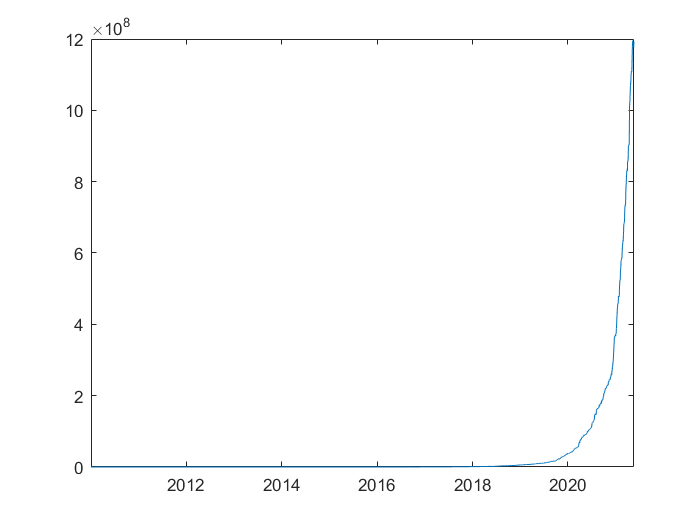


plot (cumRetPortfolio.Time, cumRetPortfolio.Variables)


maxDD = maxdrawdown(cumRetPortfolio.Variables)

maxDD =    0.050007305565684


SharpeRatio = sharpe (cumRetPortfolio.Variables)

SharpeRatio =    0.261146057175832


Write to Excel

writetimetable (cumRetPortfolio, "Trend Trading Input Output Data.xlsx", ...
    'sheet', 'cumRetPortfolio');


save tradingdata.mat 
